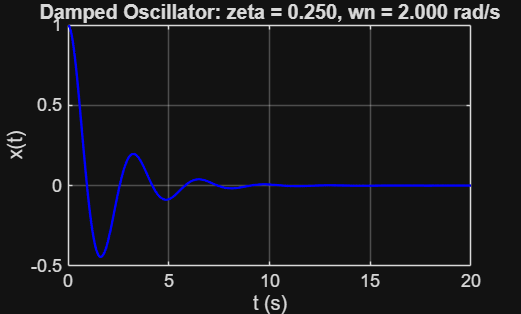


% Parameters (可調)
m = 1.0;        % 質量
k = 4.0;        % 彈性常數
% 選擇 c 以產生不同阻尼行為：
% underdamped: c < 2*sqrt(m*k)
% critical:   c = 2*sqrt(m*k)
% overdamped: c > 2*sqrt(m*k)
c = 1.0;        % 阻尼係數

% Derived
wn = sqrt(k/m);          % natural frequency (rad/s)
zeta = c/(2*sqrt(m*k));  % damping ratio

% ODE setup
tspan = [0 20];
y0 = [1; 0];    % 初始位移 1, 速度 0

odefun = @(t,y) [ y(2);
                 -(c/m)*y(2) - (k/m)*y(1) ];

opts = odeset('RelTol',1e-6,'AbsTol',1e-8);
[t,y] = ode45(odefun,tspan,y0,opts);

% Plot time response
figure;
plot(t,y(:,1),'b','LineWidth',1.2);
xlabel('t (s)');
ylabel('x(t)');
title(sprintf('Damped Oscillator: zeta = %.3f, wn = %.3f rad/s', zeta, wn));
grid on;

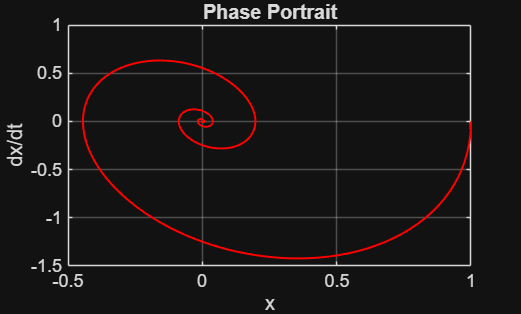


% Phase portrait
figure;
plot(y(:,1),y(:,2),'r','LineWidth',1);
xlabel('x');
ylabel('dx/dt');
title('Phase Portrait');
grid on;


% Display summary
fprintf('wn = %.4f rad/s, damping ratio zeta = %.4f\n', wn, zeta);

wn = 2.0000 rad/s, damping ratio zeta = 0.2500


if zeta < 1
    disp('Case: Underdamped (oscillatory)');
elseif abs(zeta-1) < 1e-6
    disp('Case: Critically damped');
else
    disp('Case: Overdamped (non-oscillatory)');
end

Case: Underdamped (oscillatory)
